# 複素フーリエ級数

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

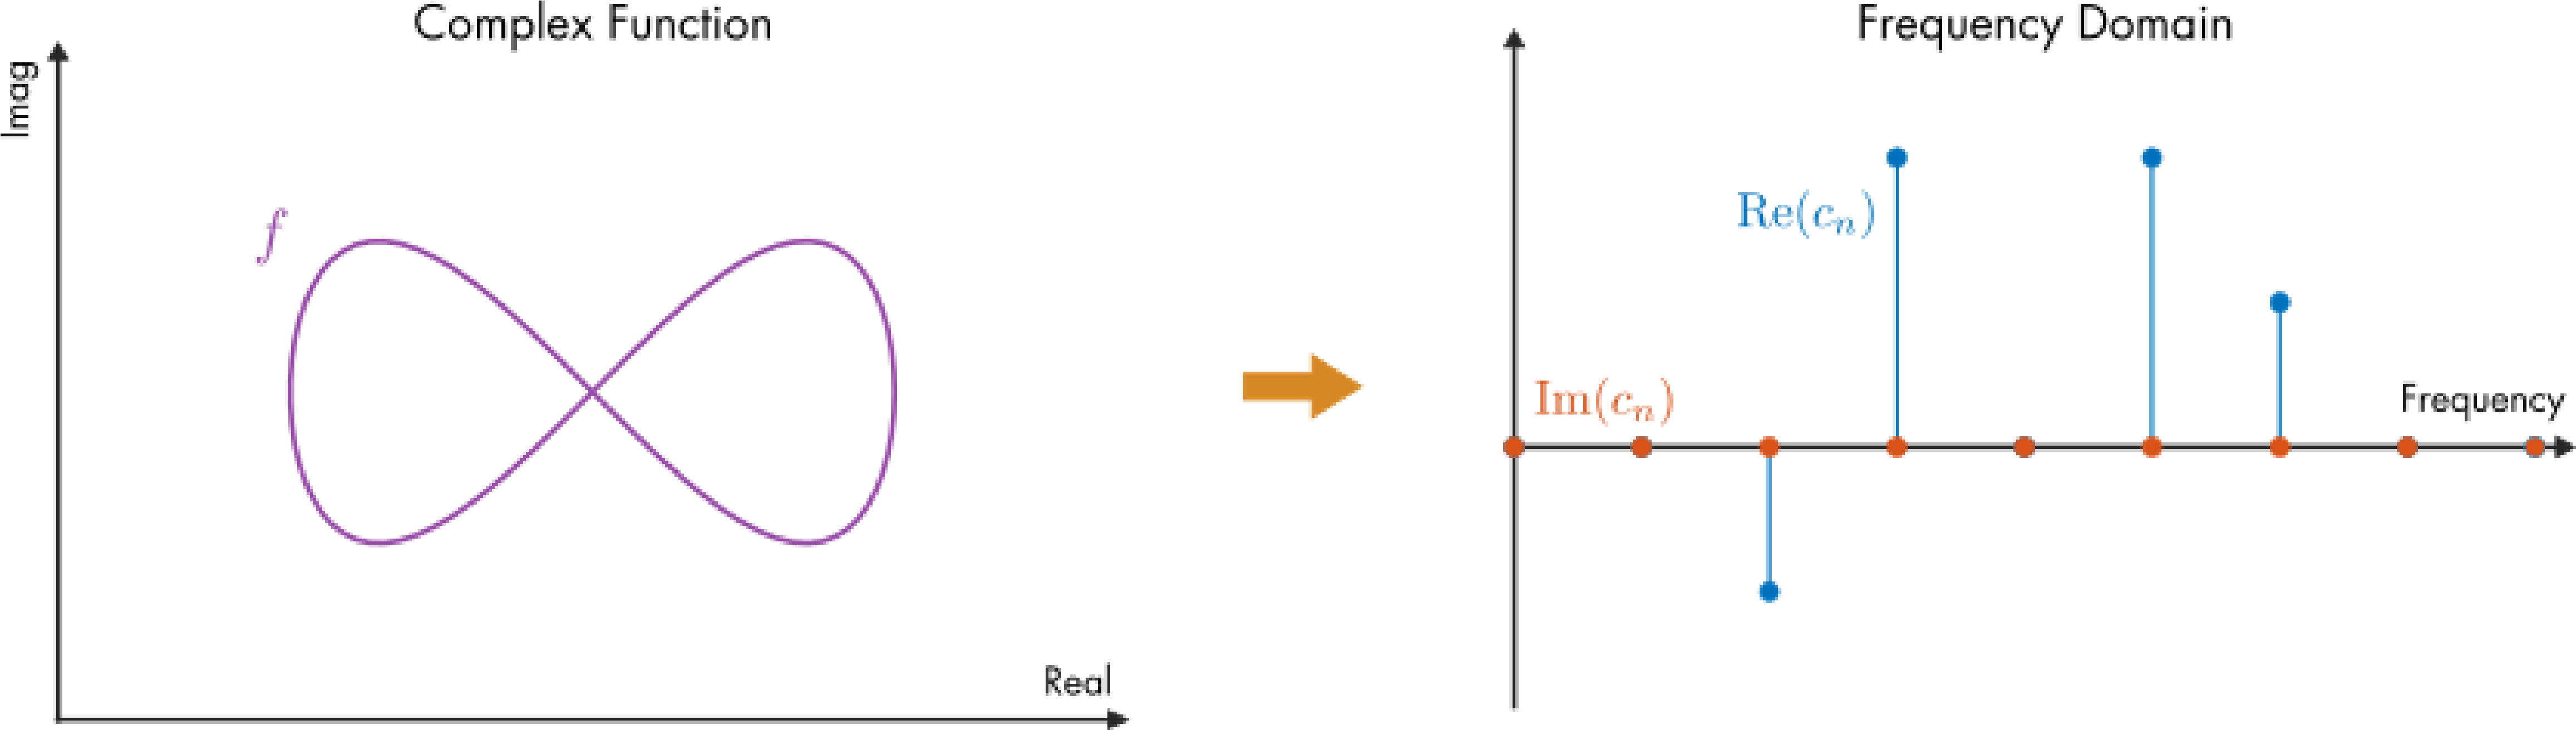

**始める前に：**

このライブスクリプトは、コードが表示され、出力がインラインで表示される状態で使用することを想定しています。MATLABツールストリップの**表示**タブの**表示**セクションで、**インラインで出力**を選択してください。または、ライブエディタウィンドウ右上のアイコン   を使って**インラインで出力**に設定することもできます。

 このライブスクリプトを操作することで、概念やコマンドの理解とともにMATLABに慣れることができます。さらに詳しい説明が必要な場合は、[MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted)（MATLABの基本を学べる無料の2時間オンラインチュートリアル）の受講を検討してください。

   最適な体験のために、指示や手順は示された順番で進めてください。前のセクションを完了してから新しいセクションに進みましょう。いくつかのセクションは前のセクションで作成された変数に依存しており、順番を守らないとエラーが発生します。

   と   のアイコンは、2種類のインタラクティブなアクティビティを示しています。   は、主にこのスクリプトで紹介された概念を、視覚的に理解するインタラクションを紹介します。 のインタラクションは、学習者が概念をどれだけ理解しているかを確認する目的で設計されており、教授による成績評価や完了チェックに使われる場合があります。

## はじめに

フーリエ級数は、サインとコサインを用いて定義することができます。


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


または、振幅 $A_n$ と位相 $\phi_n$ でパラメータ化された単一のコサインとして表すこともできます。


$$f(t) = \frac{A_0}{2} +  \sum_{n=1}^{\infty} A_n \cos\left( \frac{ n \pi } {L}  t - \phi_n \right)$$


これらの形は直感的には分かりやすいですが、扱うのが煩雑になることがあります。このレッスンでは、3つ目の形である*複素フーリエ級数*について学びます。複素数を用いることで、2組のパラメータを1組にまとめることができ、非常にコンパクトな定義が得られます。さらに、複素フーリエ級数を学ぶことで、フーリエ変換の理解にもつながります。

## オイラーの公式

数学でもっとも驚くべき公式のひとつであるオイラーの公式は、複素数を用いて指数関数と三角関数を結びつけます。


$$e^{i \theta} = \cos \theta + i \sin \theta$$


複素平面上で見ると、オイラーの公式は円を描きます。

   **課題.** 下のスライダーを0から360までゆっくり動かして、オイラーの公式で円を描いてみましょう。

thetad = 0; % In degrees
complexCircle(thetad); % Helper function that generates the plot

入力 $\theta$ を時間の線形関数にすると、オイラーの公式は角周波数 $\omega$ に依存した速さで円を描きます。


$$y(t) = e^{ i \omega t}$$


角周波数の単位はrad/sです。各成分を時間に対して個別にプロットすると、実部はコサイン曲線、虚部はサイン曲線を描きます。

   **課題**. 下のスライダーで $y(t)$ の周波数を設定し、このセクションを実行して、複素平面上で $e^{ i \omega  t}$ のアニメーションプロットと時系列を作成しましょう。

freq = 1; % frequency in Hz
 
omega = freq*2*pi; % angular frequency in rad/s
traceSineCosine(1,omega,0,1.2,true); % Helper function that traces the curve

## 複素フーリエ級数

関数 $e^{  i \omega t}$ の角周波数 $\omega$ を変えることで、標準的なフーリエ級数と同様に様々な周波数のサイン関数やコサイン関数を作ることができます。ただし、サインとコサインは関数の実部と虚部に含まれています。


$$e^{ i \omega t} = \cos ( \omega t ) + i \sin (\omega t)$$


様々な周波数を組み合わせることで、周期信号を正確に表現できます。

### 定義

複素フーリエ級数は次のように定義されます。


$$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$$


この定義において、$f$ は区間 $[-L,L]$ で周期的です。基本角周波数 $\omega_0$ は $L$ と $\omega_0 = \pi/L$ の関係にあります。複素フーリエ級数の係数は次の積分で求められます。


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


係数は実数の場合も複素数の場合もありますが、通常は複素数です。ただし、実数値関数の場合には係数間に特別な関係があります。それについては後ほど説明します。

 **演習.** この演習では、複素フーリエ級数と標準的なフーリエ級数を比較します。

**課題1.** 上記で定義した複素フーリエ級数 $f(t)$ の指数関数部分をオイラーの公式を使って展開しましょう。

**課題2.** 展開した複素級数と実数のサイン・コサイン級数を比較しましょう。


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


- 共通する部分は何ですか？

- 異なる部分は何ですか？

### 複素フーリエ級数のモード

複素フーリエ級数のモード(各周波数成分)は、実数フーリエ級数のモードよりも理解が困難です。なぜなら、実部と虚部の両方を含んでいるからです。級数の $n$ 番目のモードを考えてみましょう。


$$f_n(t) = c_n e^{\frac{i n \pi }{L} t}  = c_n \cos\left( \frac{ n \pi } {L}  t \right) + i c_n \sin \left( \frac{ n \pi } {L}  t \right)$$


例えば $c_n = 1$ のように実数のモード係数を設定すると、実部のコサイン曲線と虚部のサイン曲線が同時に得られることに注目してください。これが何を意味するのか理解するには、いくつかのモードを可視化するのが役立ちます。

   **アクティビティ**. 複素フーリエ級数アプリで複素モードを可視化しましょう。

**課題1.** 複素フーリエ級数アプリを実行しましょう。

[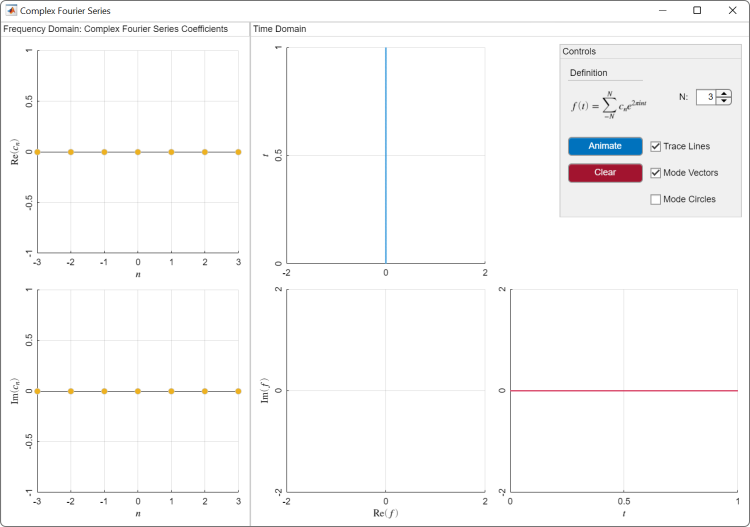](matlab: run ComplexFourierSeries)

[ComplexFourierSeriesApp.mlapp](matlab: run ComplexFourierSeriesApp)

**課題2.** 左側のパネルに周波数領域が表示されています。第2モード（$n=2$）の係数を $c_2 = 1$ になるように調整し、他の $c_n = 0$ のままにしてください。

- 係数の棒グラフをクリック＆ドラッグしてモードを調整できます。

- 最初のグラフ（係数の実部Re）だけを調整すれば十分です。

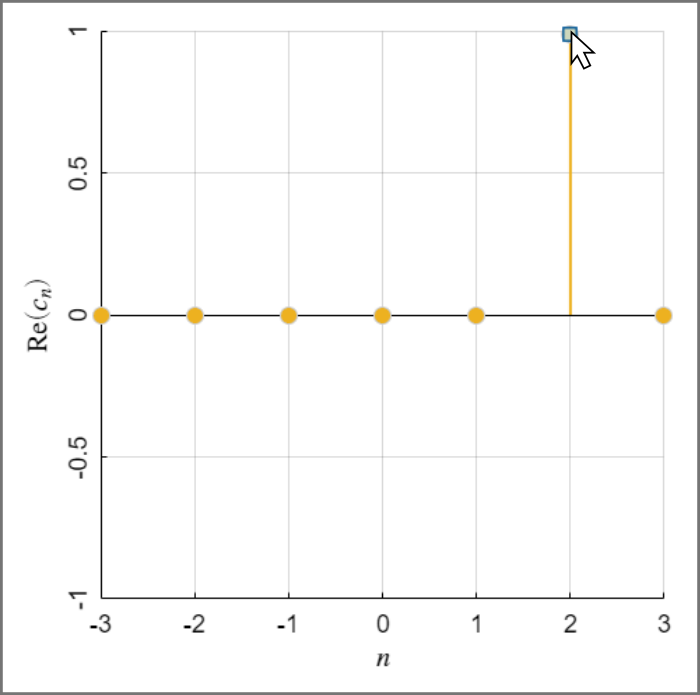

**課題3.** 各グラフに表示された結果を確認しましょう。軸ラベルや下の説明文を見て、各グラフが何を示しているかを確認してください。

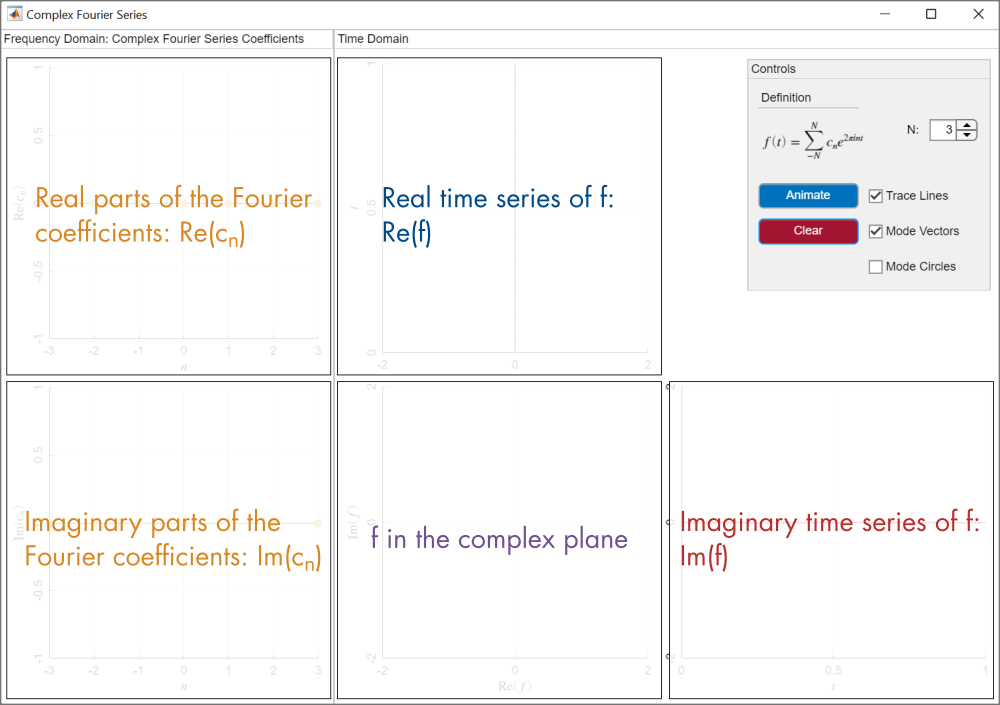

*複素フーリエ級数アプリの各グラフの説明。実時間系列では、実部が複素平面の実軸と一致するように軸が横向きになっています。*

**課題4.** **Animate** ボタンを押して、モードを時間的にアニメーションで見てみましょう。モードが実部と虚部の両方を含んでいることに注目してください。

**課題5.** クリアボタンを押して係数をリセットしましょう。

**課題6.** 第1モードの係数を $c_1 = i$（他の $c_n = 0$）に調整し、グラフをアニメーションで見てみましょう。

- モード係数の虚部を調整するには、2番目のグラフ（$\text{Im}(c_n)$)を使います。

- $c_1$ を $c_1 = 1$ から $c_1 = i$ に変更しても、複素平面のグラフは変化しません（依然として単位円を示します）。しかし、時系列グラフは変化しています。実部の時系列はどのように変化しましたか？

**課題7.** アプリをクリアし、複素係数 $c_1 = 1+i$ のモードを作成しましょう。係数の実部と虚部の両方を1に調整してください。

- 複素平面のグラフはどのように変化しますか？

- 実部・虚部の時系列はどのように変化しますか？

**課題8.** 課題2～7を、今度は高次モード n = 3 で繰り返しましょう。引き続き1つのモードだけを見てください(他は0に設定してください)。

- $n = 1$ の場合と比べて、複素平面のグラフはどのように変化しますか？

- $n = 1$ の場合と比べて、時系列グラフはどのように変化しますか？

課題2～4では、$c_1 = 1$（他の $c_n = 0$）と設定しました。これはフーリエ級数が1つのモードだけから成ることを意味します。

$f(t) = 1 e^{2 \pi i  t}  =  \cos\left(2  \pi  t \right) + i \sin \left( 2 \pi  t \right)$.

$f$ の実部は純粋な1 Hzのコサイン波（実部の時系列で観察）、虚部は純粋な1 Hzのサイン波（虚部の時系列で観察）になります。

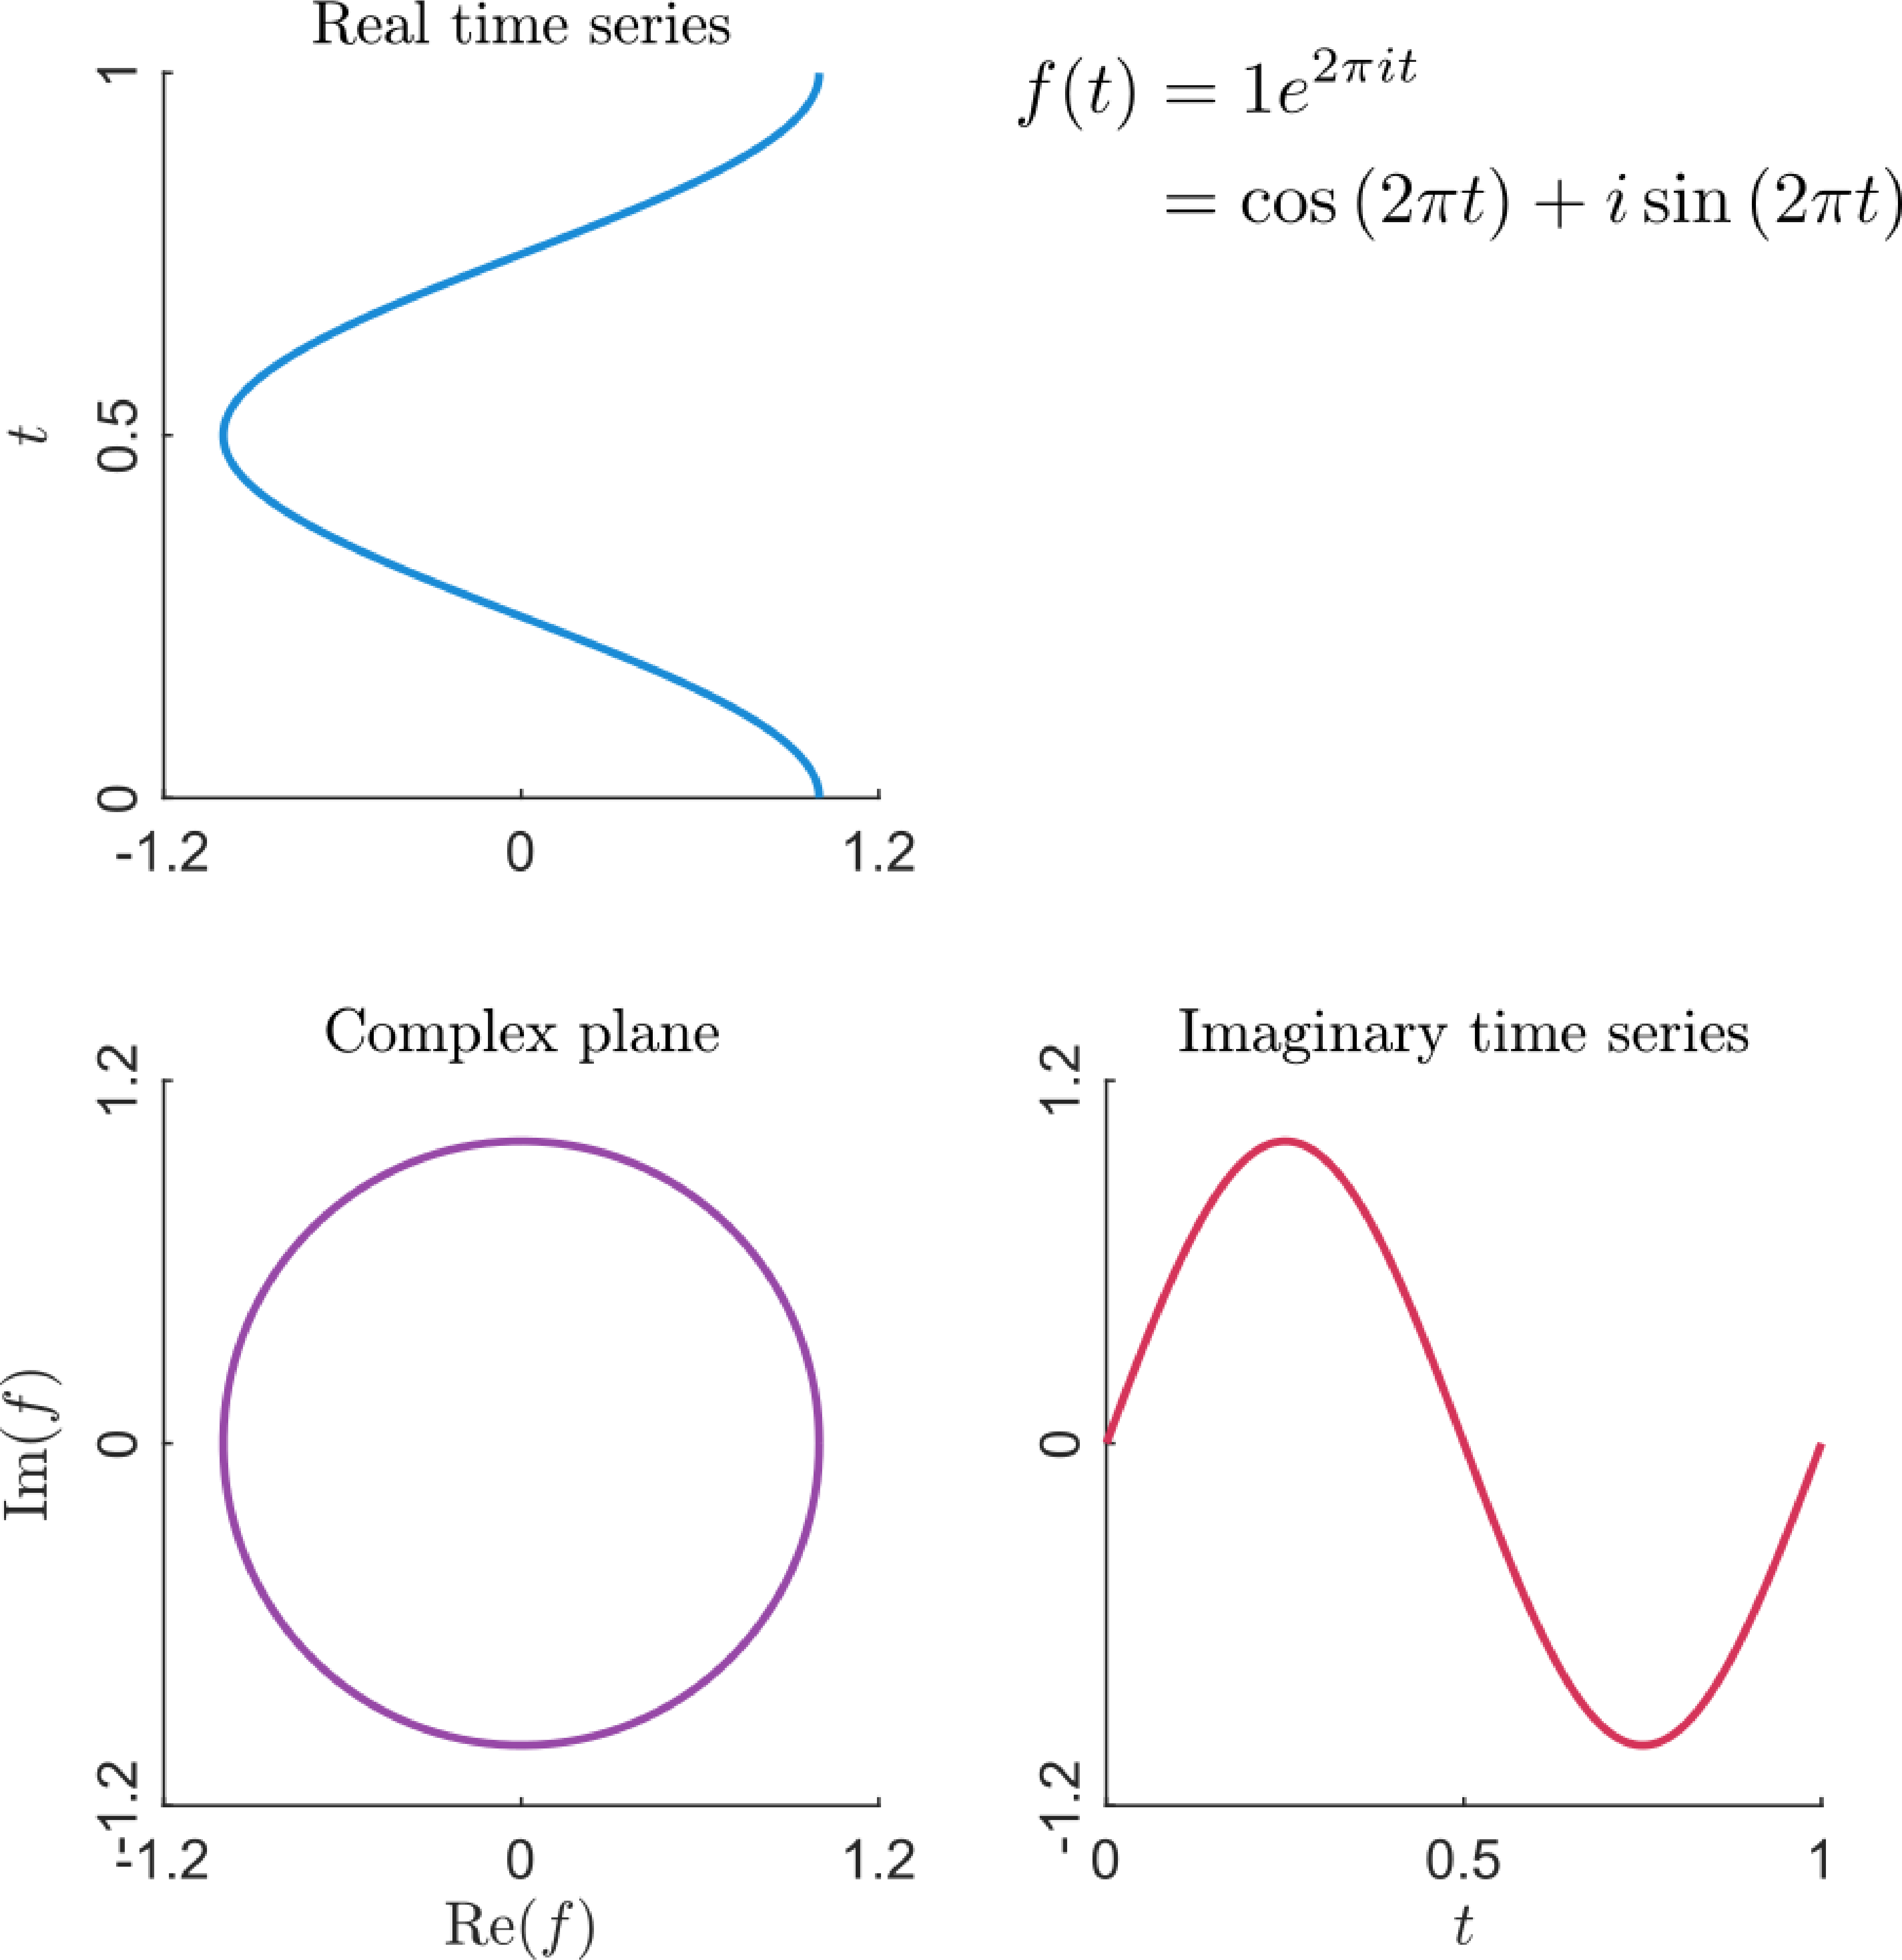

*単一モード *$c_1 = 1$* のときの *$f$* の時間領域プロット。*

 **演習.** 手計算で、$c_1 = i$ かつ他の $c_n = 0$ の場合のフーリエ級数を書き出しましょう。

- フーリエ級数 $f$ の実部と虚部はどうなりますか？

- これらの成分は、アプリで観察した時系列グラフにどのように反映されていますか？

## 複素級数による実数値関数の表現

前のアクティビティで、すべてのモードには実部と虚部があることに気づいたかもしれません。実際、どんな複素係数 $c_n$ を選んでも（0以外）、そのモードは常に実部と虚部の組み合わせを含みます。

では、これらのモードから実数値関数をどのように作るのでしょうか？たとえば、純粋な1 Hzのサイン波を作るにはどんな係数が必要でしょうか？


$$y(t) = \sin( 2 \pi t)$$


答えは、正の周波数と負の周波数を「ちょうどよく」組み合わせて、虚部が「打ち消し合う」ようにすることです。

### 複素モードから実モードを作る

   **アクティビティ**. このアクティビティでは、複素モードを組み合わせて実モードを作成します。

**課題1.** 複素フーリエ級数アプリを実行しましょう。

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeriesApp.mlapp](matlab: run ComplexFourierSeriesApp)

**課題2.** 実数値(Re)のフーリエ係数 $c_1 = 0.5$ に設定しましょう。

**課題3.** 同じ大きさで符号が逆の周波数のフーリエ係数（$c_{-1}$)を調整することで、実信号を作ることができます。$c_{-1}$ の実部や虚部を調整して、実信号を作りましょう。

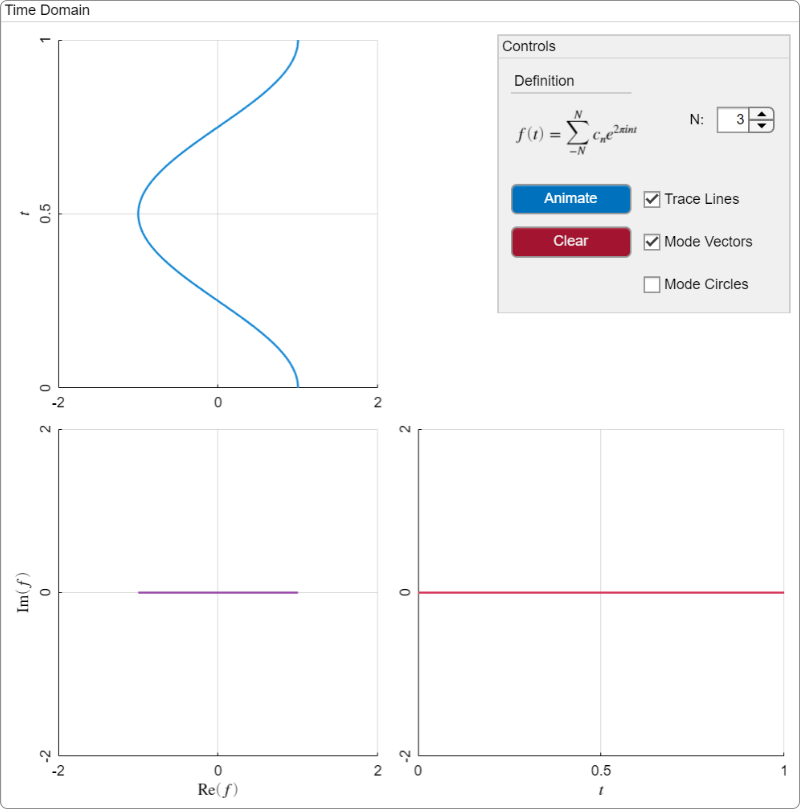

*正しくできていれば、実部がコサイン曲線となり、虚部はゼロになります。*

**課題4.** **課題2**と**課題3**で使った2つの係数を使って、手計算でフーリエ級数を書き出しましょう。アプリで定義されている式を使ってください：


$$f(t) = \sum_{-N}^N c_n e^{ 2 \pi i n t}$$


次に、オイラーの公式を使って複素指数関数を展開し、結果を簡単にしましょう。正しければ、


$$f(t) = \cos(2 \pi t)$$


**課題5.** プロットをアニメーションで見てみましょう。両方の複素モードが存在し、それらが「ちょうどよく」組み合わさって虚部が「打ち消し合う」ことに注目してください。

- 「Mode Circles」チェックボックスを選択してアニメーションボタンを押すと、各複素モードの円運動を可視化できます。

- 円の中の棒の動きを見てみましょう。2つの複素円は同じ周波数・大きさですが、逆方向に回転していることに注目してください。これは負の周波数成分を使った結果です。

**課題6.** **課題2～4**で、複素フーリエ変換から実数値1 Hzコサイン波を作る係数を見つけました。**課題4**で展開した $c_1$ と $c_{-1}$ だけを使った式を考えてみましょう：


$$f(t) = c_{-1} e^{ - 2 \pi i t} + c_{1} e^{ 2 \pi i t}$$


実数値の1 Hzサイン波を作るには、どんな複素係数 $c_1$ と $c_{-1}$ を選べばよいでしょうか？下に答えを記入してください。

**ヒント：** オイラーの公式を使って複素指数関数を展開しましょう。

  **プロ・チップ**. 複素数は標準的な数学記法で書けます。たとえば $w = 3+2i$ は、MATLAB では

% Replace NaN with your answers
cm1 = NaN; % c_{-1}
c1 = NaN; % c_1

**課題7.** **課題6**で導出した係数をアプリ内で設定し、結果を確認しましょう。その後、プロットをアニメーションで可視化させてください。

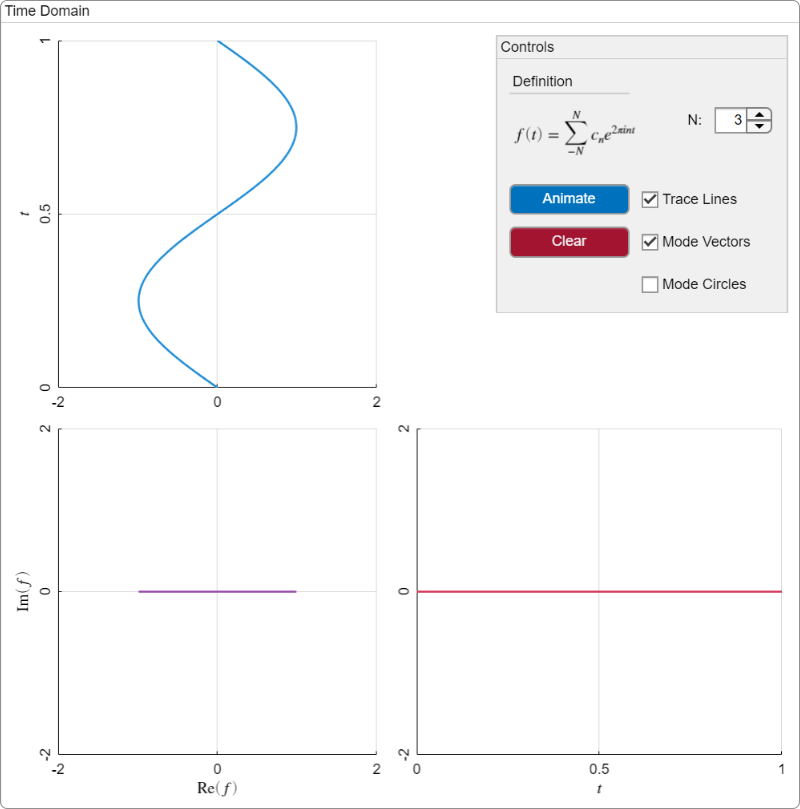

*正しい結果*

#### **実数級数と複素級数の関係**

一般に、虚数部分を消して実数だけで関数を表すには、負の周波数係数 $c_{-n}$ が対応する正の周波数係数 $c_{n}$の複素共役でなければなりません：$c_{-n} = {c_n}^*$. $a + bi$ の複素共役は $a - bi$ であることを思い出してください。この条件が成立すると、複素級数の中の虚数の部分が打ち消されて、結果として実数の関数になります。この事実は、実フーリエ級数と複素フーリエ級数の関係につながります。実数のサイン・コサインフーリエ級数を考えましょう：


$$f(t) = \frac{a_0}{2}  + \sum_{n=1}^\infty a_n \cos\left( \frac{ n \pi } {L}  t \right) + b_n \sin \left( \frac{ n \pi } {L}  t \right)$$


対応する複素フーリエ級数は

$f(t) = \sum_{-\infty}^\infty c_n e^{ \frac{i n \pi}{L} t}$    ここで    $c_n = \frac{1}{2} \left\{
 \begin{array}{rl} 
a_0; & n = 0 \\ 
a_n - i b_n; & n > 0 \\ 
a_{-n} + i b_{-n}; & n < 0 \\ 
 \end{array}
 \right.$

 **演習.** 上記の $a_n$ と $b_n$ で複素フーリエ級数を書き、オイラーの公式を適用しましょう。結果が実フーリエ級数と等価であることを確認してください。

### モードの組み合わせ

前回のアクティビティでは、複素モード(周波数成分)を組み合わせて実数のサインやコサインを作りました。これらの実数の構成要素を使えば、実フーリエ級数と同じように多くの周波数を組み合わせて周期関数を再現することができます。

   **アクティビティ** このアクティビティでは、いくつかの複素モードを組み合わせて実数値関数を作成します。

**課題1.** 複素フーリエ級数アプリを実行してください。

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeriesApp.mlapp](matlab: run ComplexFourierSeriesApp)

**課題2.** フーリエ係数を設定して、次の実数値関数を生成してください：


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


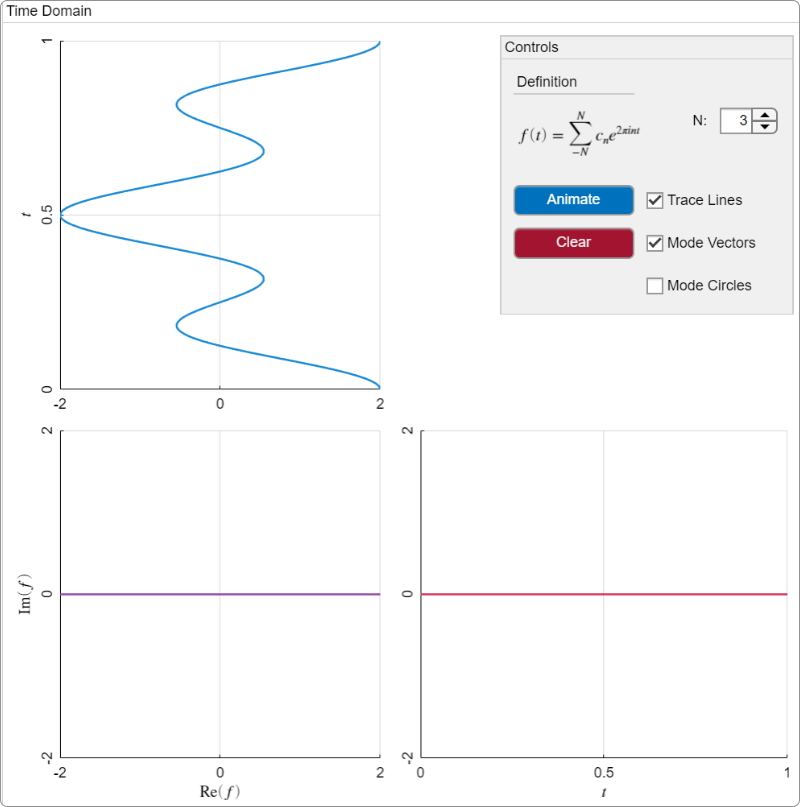

*正しければ、関数は1 Hzと3 Hzのサイン波の和として表示されます*

**ヒント**：まず正の周波数を使ってコサイン曲線を作成しましょう。その後、負の周波数を使って虚部を「打ち消す」ようにしてください。

**課題3.** モード円を描画した場合としない場合の両方でプロットをアニメーションさせてください。高周波モードほど低周波モードよりも速く回転し、時間領域プロットで高周波の振動を生み出していることに注目しましょう。

**課題4.** **課題2**と**課題3**を、次の実数値関数について繰り返してください


$$f(t) = 0.5 + \sin(2 \pi t) + \cos( 2 \pi t) - \sin( 4 \pi t)$$


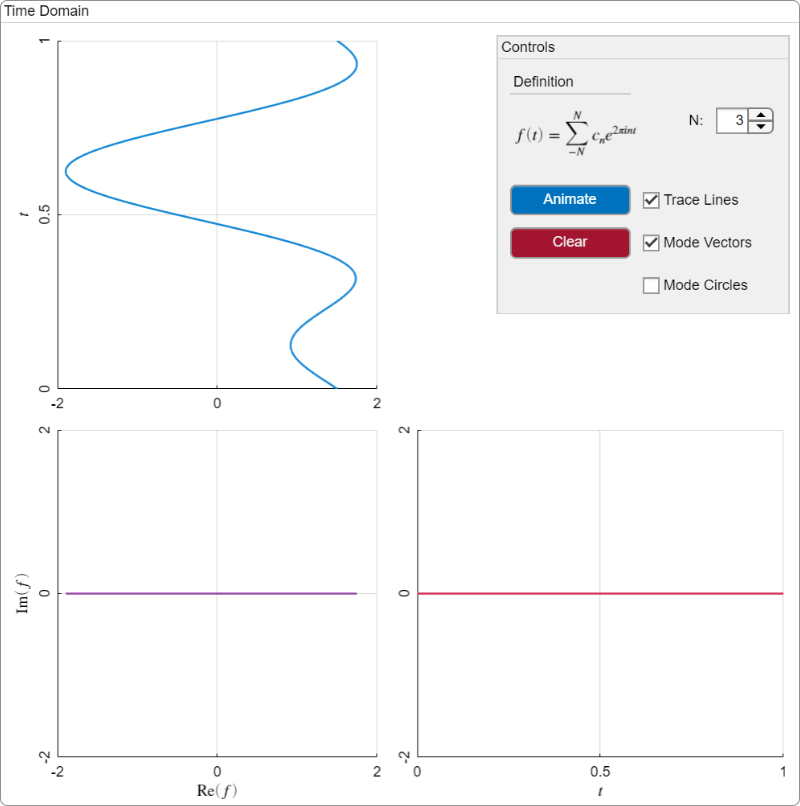

*正しい結果*

 **演習.** 次の積分公式を使いましょう


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


$L = 0.5$（アプリの定義に合わせるため）として、この関数の複素級数係数を導出してください


$$f(t) = \cos( 2 \pi t ) + \cos(6 \pi t )$$


アクティビティで求めた結果と一致しますか？

**ヒント**：まずサインとコサインを複素指数関数で書き直しましょう。次の公式を使います：

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    および    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

離散信号の複素フーリエ級数は、係数公式の積分を離散的に近似することで推定できます。

 **例.** このセクションを実行して、ギターの音に対して計算された複素フーリエ級数係数 $c_n$ を確認しましょう。

% This code reads and plays the guitar sound 
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% This helper function computes the complex Fourier coef
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
plotComplexCoef(freq,c); % Generates the plot
 

 **考えてみましょう。**

- どの周波数が支配的ですか？

- プロットが $n = 0$ を中心に（わずかな違いはありますが）対称になっていることに注目してください。なぜでしょうか？

- 負の周波数にはどんな意味や目的があるのでしょうか？

### 複素級数の大きさと位相

複素係数 $c_n$ を「標準形」つまり（$a+bi$）の形で理解することは大切ですが、グラフにすると少し分かりにくいことがあります。実数級数と同様に、複素係数の位相と大きさをプロットすることで、周波数領域をより明確に把握できます。そのためには、複素係数を位相と大きさで書き直す必要があります。そのためには、複素数を次のような形に書き直します：


$$a + bi = A e^{i \phi}$$


ここで $A$ は大きさ、$\phi$ は位相です。この形は*極形式*と呼ばれます。

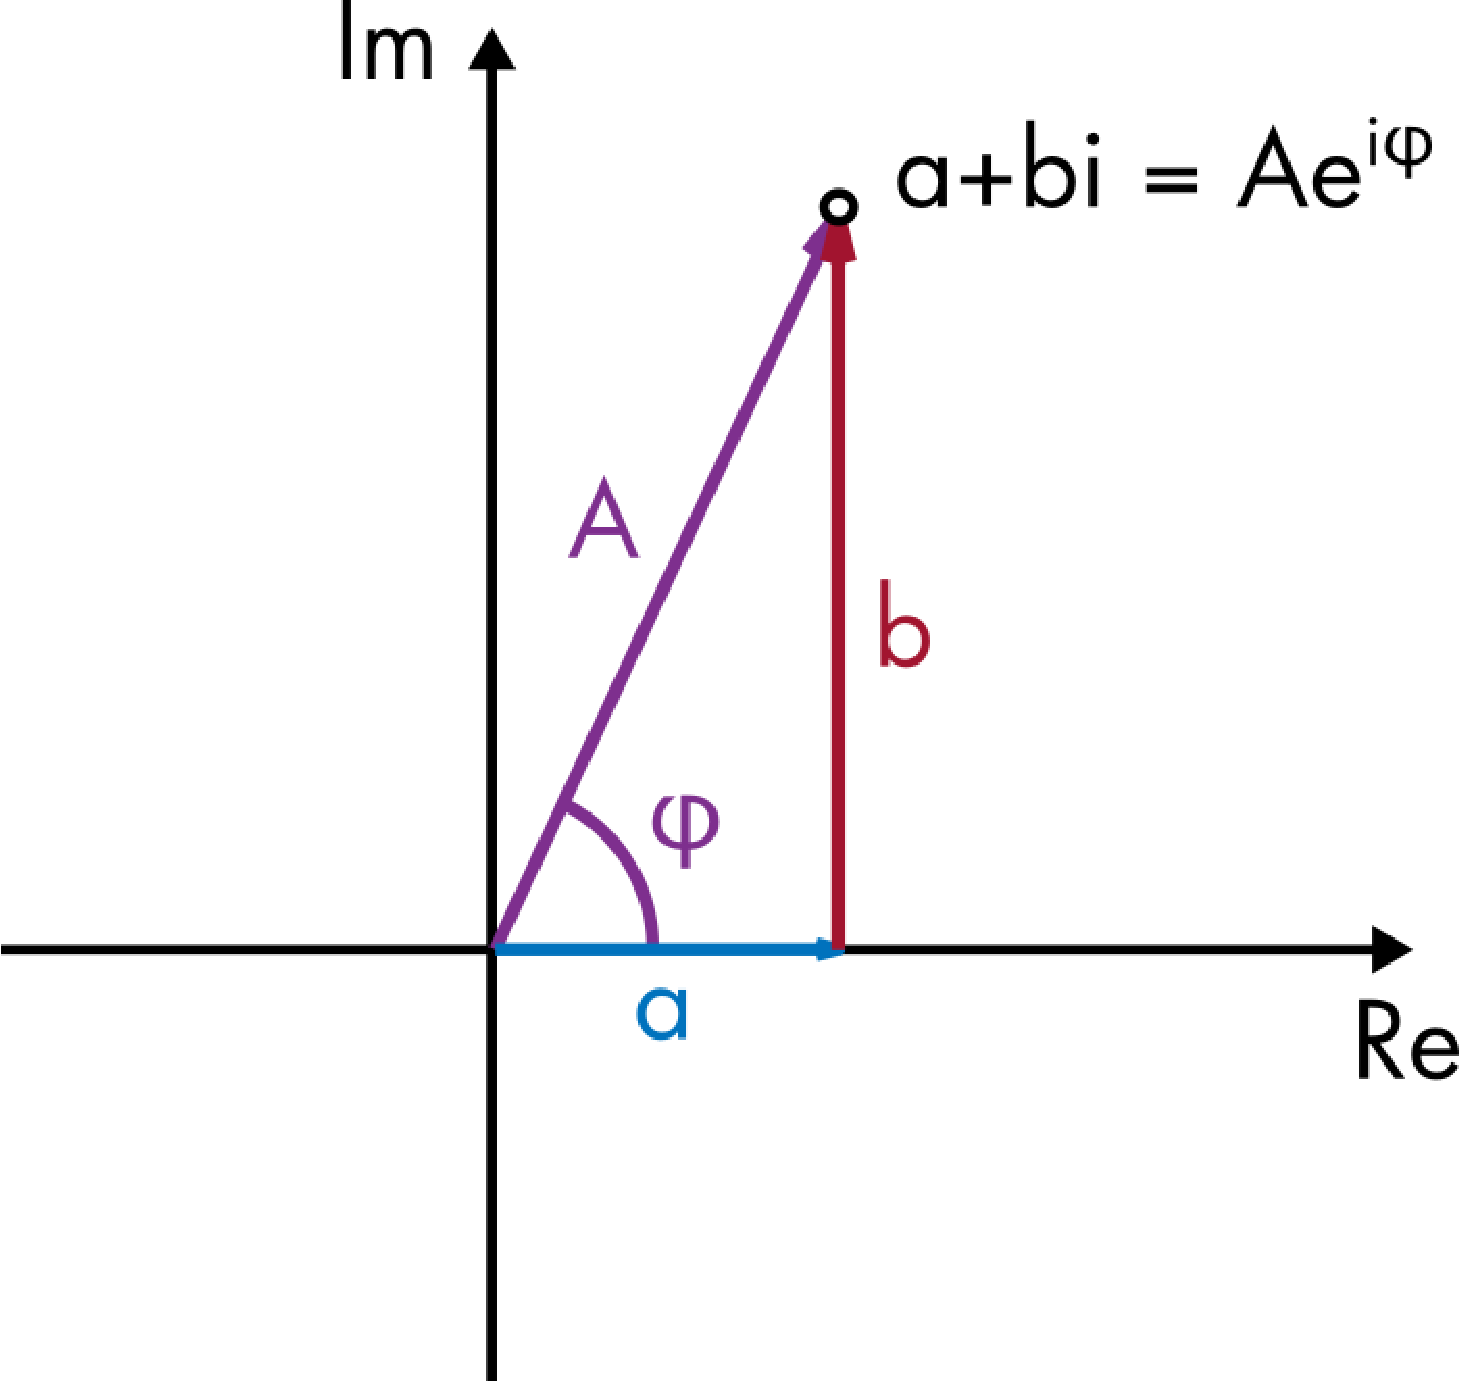

*複素平面上で可視化した複素数の標準形と極形式*

大きさは $a + bi$ の成分から次のように計算できます：


$$A= \sqrt{ a ^2 + b^2}$$


位相は `atan2` を使って計算できます：


$$\phi = \text{atan2}\left(b,a\right)$$


見覚えがありますか？これらは実フーリエ級数のサイン係数とコサイン係数から大きさと位相を求めるときと全く同じ公式です。これらの公式を使えば、任意の複素フーリエ級数モードの大きさと位相シフトを係数 $c_n$ から直接計算できます。

   **アクティビティ** 下のコードは、複素係数を極形式で表した、2 Hzの周波数成分だけを取り出した複素モード $f_2(t) = c_2 e^{4 \pi i t}$ のプロットをアニメーション表示します：$c_2 = A e^{i \phi}$。

- 係数 $A$ の大きさを変更してアニメーションを実行してください。モードはどのように変化しますか？

- $c_2$ の位相 $\phi$ を変更してアニメーションを実行してください。モードはどのように変化しますか？

A = 1; % Complex coefficient magnitude
phi = 0; % Complex coefficient phase
 
cn = A*exp(1i*phi)
omega = 2*2*pi; % angular frequency of the mode in rad/s
traceSineCosine(A,omega,phi,3,true); % Helper function that generates the plot

実際の信号の複素フーリエ係数を計算した後、位相と大きさを求めてフーリエ領域の直感的なプロットを作成できます。

 **演習.** このセクションでは、ギター音の大きさと位相のプロットを確認します。

**課題1.** このセクションを実行して複素フーリエ係数を計算してください。複素係数はベクトル `c` に格納されます。

% This code reads and plays the guitar sound 
[yGuitar,FsGuitar] = audioread("Dnote.mp3");
soundsc(yGuitar,FsGuitar)
% This helper function computes the complex Fourier coef
[freq,c] = computeGuitarComplexFourierCoef(yGuitar,FsGuitar);
 

**課題2.** 複素係数 `c` の大きさと位相を計算してください。公式と次の関数を使うことができます：[`real`](https://www.mathworks.com/help/matlab/ref/real.html)、[`imag`](https://www.mathworks.com/help/matlab/ref/imag.html)、[`atan2`](https://www.mathworks.com/help/matlab/ref/atan2.html)、[`sqrt`](https://www.mathworks.com/help/matlab/ref/sqrt.html)、または [`abs`](https://www.mathworks.com/help/matlab/ref/abs.html) および [`angle`](https://www.mathworks.com/help/matlab/ref/angle.html) 関数を使っても構いません。

% Compute the magnitude and phase
A = NaN;
phi = NaN;

**課題3.** 大きさ `A` を `freq` に対してステムプロットで表示してください。[`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) 関数を使用します。周波数の範囲は [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) 関数を使って [-800,800] に設定してください。

figure % Creates a new figure
% Create your stem plot here



負の周波数の大きさは、対応する正の周波数の大きさと等しいことに注目してください。これは実信号の場合常に成り立ちます。なぜなら、負の周波数の係数は正の係数の複素共役になっているからです：$c_{-n} = {c_n}^*$

**課題4.** **課題2** で計算した位相 `phi` のstemプロットを作成してください。[`stem`](https://www.mathworks.com/help/matlab/ref/stem.html) 関数を使用します。周波数の範囲は [`xlim`](https://www.mathworks.com/help/matlab/ref/xlim.html) 関数を使って `[-800,800]` に設定してください。

figure % Creates a new figure
% Create your stem plot here



この信号において、ほとんどの位相は無視できます。なぜなら、それらは大きさがごく小さい周波数で現れるからです。

**課題5.** 2つの低周波数のピーク（146.6 Hz と 294.4 Hz）の位相をラジアンで特定してください。まず、[`xline`](https://www.mathworks.com/help/matlab/ref/xline.html) を使って正しい周波数に垂直線を引きます。例えば、146.6 Hz に垂直線を引くには `xline(146.6)` を使います。

周波数をマークした後、ステムプロット上の該当箇所をクリックしてデータチップを表示し、そこから位相を読み取ることができます。

% Add your xlines here



**ヒント：** 正しい点をクリックするのが難しい場合は、 を使ってプロットを新しいウィンドウに表示し、拡大してください。また、ズームツールで該当領域を拡大することもできます。

% Record your answers here
phase_147Hz = NaN; % In radians
phase_294Hz = NaN; % In radians

## **複素関数**

実数値関数は、複素フーリエ級数の特別なケースにすぎません。実は、複素フーリエ級数を使うとさまざまな複素関数を表現できます。複素関数は実部と虚部を持ちます：


$$f(t) = f_{re}(t) + i f_{im}(t)$$


   **アクティビティ**．レムニスケートは、8の字のような形をした曲線です。この曲線は、複素フーリエ級数のわずか4つのモードで表さ鵜ことができます。このアクティビティでは、アプリでレムニスケートを描きます。レムニスケートは次の複素値関数で表されます


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


**課題1.** 複素フーリエ級数アプリを実行してください。

[](matlab: run ComplexFourierSeries)

[ComplexFourierSeriesApp.mlapp](matlab: run ComplexFourierSeriesApp)

**課題2.** レムニスケートの最初の2つのモードは、1 Hz の実数コサイン曲線を表します。下図の実数コサインのグラフを作成するようにフーリエ係数を調整してください。

**課題3.** $n = 2$ モードの係数を調整して、関数の虚部 $ \frac{i}{2} \sin (4 \pi t)$ を作成してください。正しくできていれば、複素プロットにレムニスケートが表示されます。

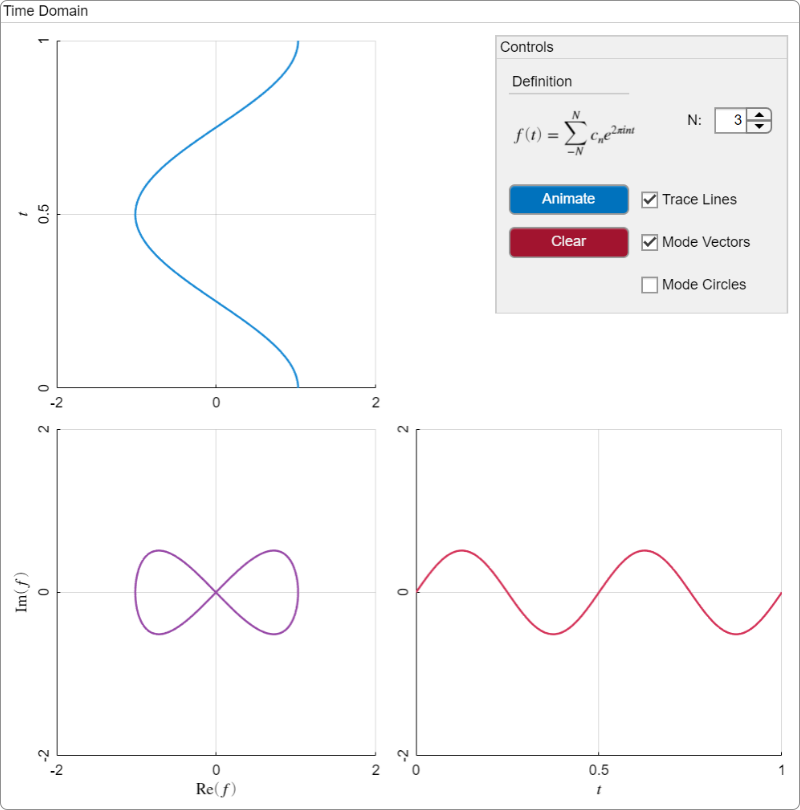

**課題4**．プロットをアニメーション化してください。

 **演習.** 次の積分公式を使ってください


$$c_n = \frac{1}{2L} \int_{-L}^{L} y(t) e^{ -\frac{i n \pi}{L} t} dt$$


$L = 0.5$（アプリの定義に合わせるため）として、レムニスケート関数の複素級数係数を導出してください：


$$f(t) = \cos (2 \pi t) + \frac{i}{2} \sin (4 \pi t)$$


アクティビティで求めた結果と一致しますか？

**ヒント**：まず、サインとコサインを複素指数関数で書き直してください。次の公式を使います：

$\cos \theta = \frac{e^{i \theta} + e^{- i \theta}}{2}$    および    $\sin \theta = \frac{e^{i \theta} - e^{- i \theta}}{2i}$

[⇦ メインメニューに戻る](matlab:open('../MainMenu.mlx'))

**ヘルパー関数**

function complexCircle(theta)
    % This function traces out a circle in the complex plane
    % With labels for Euler's formula
    
    f = exp(1i*theta * pi/180);
    thetaVec = 0:theta;
    fc = exp(1i*thetaVec*pi/180);
    
    colors = lines(7);
    
    figure
    quiver(0,0,real(f),imag(f),"off","LineWidth",1,"color",colors(4,:))
    hold on
    plot(real(fc),imag(fc),"LineWidth",1,"color",colors(4,:))
    quiver(0,0,real(f),0,"off","LineWidth",1,"color",colors(1,:))
    quiver(real(f),0,0,imag(f),"off","LineWidth",1,"color",colors(7,:))
    text(real(f)/2,0,"$\cos \theta$","Interpreter","latex",...
        "VerticalAlignment","top","HorizontalAlignment","center")
    text(real(f),imag(f)/2,"$\sin \theta$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","left")
    text(real(f)*1.1,imag(f)*1.1,"$e^{i \theta}$","Interpreter","latex",...
        "VerticalAlignment","middle","HorizontalAlignment","center")
    hold off
    
    axis equal
    axis(1.3*[-1 1 -1 1])
    xlabel("Re")
    ylabel("Im")
    title("Complex plane")
    xticks([-1,0,1])
    yticks([-1,0,1])
end

function [freq,c] = computeGuitarComplexFourierCoef(y,Fs)
    % This function estimates the complex coef. for the 
    % complex Fourier transform using the trapezoid rule

    Nmodes = 1000;
    yc = y(1e4:5e4);
    
    tc = 1/Fs*(0:(length(yc)-1));
    L = tc(end)/2; % The domain is assumed to be 2L
    nvec = -Nmodes:Nmodes;
    freq = nvec/(2*L); % Frequencies

    % Estimate coefficients using trapezoid rule
    c = zeros(1,numel(nvec));
    for k = nvec + Nmodes + 1
        c(k) = 1/(2*L)*trapz(tc,exp(-1i*nvec(k)*pi/L*tc).*yc);
    end
end


function pFig = figPos(ax,p)
    % This function computes the position of points
    % in the figure

    axUnits = ax.Units;
    ax.Units = 'normalized';
    pos = ax.InnerPosition;

    % Shifted so that the origin is at the lower-left corner
    x = p(1)-ax.XLim(1);
    y = p(2)-ax.YLim(1);
    
    % Compute the position of the point in the figure
    xFig = x*(pos(3))/(ax.XLim(2) - ax.XLim(1)) + pos(1);
    yFig = y*(pos(4))/(ax.YLim(2) - ax.YLim(1)) + pos(2);
    
    pFig = [xFig,yFig];
    ax.Units = axUnits;
end

function traceSineCosine(mag,omega,phi,magLim,animateFlag)
    % This function generates the animation of a
    % single Fourier mode
    %
    % Mag: magnitude
    % Omega: angular frequency (rad/s)
    % Phi: phase shift (rad)
    % magLim: axis limits in terms of magnitude
    % animateFlag: whether or not to animate

    freq = omega/(2*pi);

    % This defines the function
    Nt = 150;
    tvec = linspace(0,1,Nt);
    fvec = mag*exp(freq*2*pi*1i*tvec + 1i*phi);
    
    % Appearance settings
    timeColors = [     0    0.4470    0.7410;
        0.7350    0.1000    0.2500;
        0.4940    0.1840    0.5560]+0.1;
    
    imLims = magLim*[-1,1]; % Im limits on complex plane
    reLims = magLim*[-1,1]; % Re limits on complex plane       
    
    lwSeries = 1.25;
    lw = 0.75;

    % Set up the axes
    figure("position",[1,1,700,700])
    ax1 = subplot(2,2,3);
    ax2 = subplot(2,2,1);
    ax3 = subplot(2,2,4);
    
    % Plots
    reLine = plot(ax2,tvec*0,tvec,...
        "linewidth",lwSeries,"color",timeColors(1,:));
    imLine = plot(ax3,tvec,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(2,:));     
    hold(ax1,"on")
    cmplxLine = plot(ax1,tvec*0,tvec*0,...
        "linewidth",lwSeries,"color",timeColors(3,:));
    arrow = quiver(ax1,0,0,0,0,"off","LineWidth",1,"color",timeColors(3,:));
    hold(ax1,"off")

    % Change graph appearance: complex plane
    set(ax1,"XLimMode","manual","YLimMode","manual")
    box(ax1,"off")
    xlim(ax1,reLims)
    ylim(ax1,imLims)
    xticks(ax1,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax1,[imLims(1), mean(imLims),imLims(2)])
    xlabel(ax1,"Re$(f)$","interpreter","latex")
    ylabel(ax1,"Im$(f)$","interpreter","latex")
    title(ax1,"Complex plane","Interpreter","latex")
    ytickangle(ax1,90)
    
    % Graph appearance: real 
    box(ax2,"off")
    set(ax2,"XLimMode","manual","YLimMode","manual")
    xlim(ax2,reLims)
    ylim(ax2,[tvec(1),tvec(end)])
    xticks(ax2,[reLims(1), mean(reLims),reLims(2)])
    yticks(ax2,[tvec(1), mean(tvec),tvec(end)])
    ylabel(ax2,"$t$","interpreter","latex")
    title(ax2,"Real time series","Interpreter","latex")
    ytickangle(ax2,90)
    
    % Graph appearance: imaginary
    box(ax3,"off")
    set(ax3,"XLimMode","manual","YLimMode","manual")
    ylim(ax3,imLims)
    xlim(ax3,[tvec(1),tvec(end)])
    yticks(ax3,[imLims(1), mean(imLims),imLims(2)])
    xticks(ax3,[tvec(1), mean(tvec),tvec(end)])
    xlabel(ax3,"$t$","interpreter","latex")
    title(ax3,"Imaginary time series","Interpreter","latex")
    ytickangle(ax3,90);
    
    crossLine1 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(1,:)+0.1);
    crossLine2 = annotation("line",[0,0],[0,0],...
        "LineStyle","-","LineWidth",lw,"color",timeColors(2,:)+0.1);
    
    kvec = 1:numel(tvec);
    if(~animateFlag)
        kvec = kvec(end);
        delete(crossLine1);
        delete(crossLine2);
    end

    for k = kvec
        t = tvec(k);
        f = fvec(k);
        
        % This code creates the connecting lines
        pComplex = [real(f),imag(f)];
        pReal = [real(f),t];
        pImag = [t,imag(f)];
        
        pCFig = figPos(ax1,pComplex);
        pRFig = figPos(ax2,pReal);
        pIFig = figPos(ax3,pImag);
        
        % Update the curves
        cmplxLine.XData = real(fvec(1:k));
        cmplxLine.YData = imag(fvec(1:k));
        
        reLine.XData = real(fvec(1:k));
        reLine.YData = tvec(1:k);
        
        imLine.XData = tvec(1:k);
        imLine.YData = imag(fvec(1:k));
        
        arrow.UData = real(fvec(k));
        arrow.VData = imag(fvec(k));
        
        % Create annotation between the axes
        p1 = [real(f),imag(f)];
        p2 = [real(f),t];
        p3 = [t,imag(f)];
        
        p1Fig = figPos(ax1,p1);
        p2Fig = figPos(ax2,p2);
        p3Fig = figPos(ax3,p3);
        
        if(animateFlag)
            crossLine1.X = [p1Fig(1),p2Fig(1)];
            crossLine1.Y = [p1Fig(2),p2Fig(2)];
            
            crossLine2.X = [p1Fig(1),p3Fig(1)];
            crossLine2.Y = [p1Fig(2),p3Fig(2)];
        end

    
        drawnow
    end
end

function plotComplexCoef(freq, c)
    % Creates a plot of the real and imaginary
    % parts of the complex coefficients
    figure("position",[1,1,900,325])
    stem(freq,real(c),"Filled")
    hold on
    stem(freq,imag(c),"Filled")
    hold off
    xlabel("Frequency (Hz)")
    ylabel("Coefficient value")
    legend("Re(c_n)","Im(c_n)")
    title("Frequency domain")
    xlim([-800,800])
end